n = 30;

image = imread("hallon.jpg");
calcCIE(image)

ans = 	1.0e+03 *

    4.9489   -0.4911    2.2223


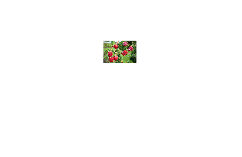

imshow(image)

reproduce(image,n)

load databaseImageCIEs.mat
databaseImageCIEs

databaseImageCIEs = databaseImageCIEs(:,:,1) =

   27.7043
   22.5305
   47.1959
   43.6277
   47.5344
   44.1427
   32.5165
   76.6802
   49.2154
   56.9855
   53.8701
   15.7227
   27.1535
    5.1715
   28.7155
   11.1467
   65.0358
   44.5237
   45.0680
   55.9748
   33.2188
   23.9649
   80.1240
   42.9229
   66.3891
   42.5063
   39.6841
   63.8607
   37.9082
   35.2597
   20.0990
   60.8386
   18.2708
   29.6832
   20.8551
   17.6253
   46.4423
   48.8186
   92.0360
   19.8914
   40.7914
   55.3101
   40.6146
   83.4719
   84.2015
   56.8384
   58.4752
   75.6757
   62.0951
   30.1052
   21.3535
   10.9721
   32.2870
   60.3576
   79.9843
   87.3892
   38.6050
   25.1765
   13.3672
   26.9841
   44.0834
   38.8487
   58.8608
   37.2160
   53.0362
   74.4252
   83.3518
   13.9467
   69.4619
   54.0276
   27.3909
   40.3752
   53.2097
   60.1360
   21.5910
   42.6185
   40.5581
   56.7817
   71.8964
   45.0809
   61.4177
   22.7819
   46.5349
   44.8761
   38.9066
   33.1442
   20.

% clear
% path = "C:\Users\gayat\Documents\TNM097\Projekt\database";
% filePattern = fullfile(path, '*.jpg'); 
% theFiles = dir(filePattern);
% n = 30;
% 
% nrOfImages = length(theFiles);
% databaseCIE = zeros(nrOfImages,3)
% 
% for k = 1 : nrOfImages
% 
%     % Load next image
%     baseFileName = theFiles(k).name;
%     fullFileName = fullfile(theFiles(k).folder, baseFileName);
%     Image = im2double(imread(fullFileName));
%     
%     % Resize and save im
%     imSize = size(Image);
%     shorter = imSize(:,2);
%     longer = imSize(:,1);
% 
%     if shorter > longer
%         temp = shorter;
%         shorter = longer;
%         longer = temp;
%     end
% 
%     Image = Image(1:shorter, 1:shorter, :);
% 
%     Image = imresize(Image, [n, n]);
%     imwrite(Image, "database_rescaled\" + baseFileName);
% 
% 
%     % Save CIE value of image
%     CIE = calcCIE(Image);
%     databaseCIE(k,:) = CIE;
% end
% 
% save("databaseCIE", "databaseCIE")

%% Calc CIE for all images
path = "C:\Users\gayat\Documents\TNM097\Projekt\database_rescaled";
filePattern = fullfile(path, '*.jpg'); 
theFiles = dir(filePattern);
nrOfImages = length(theFiles);

databaseImageCIEs = zeros(nrOfImages,3);

for k = 1 : nrOfImages
    % Load next image
    fullFileName = fullfile(theFiles(k).folder, theFiles(k).name);
    Image = im2double(imread(fullFileName));
    databaseImageCIEs(k,:) = calcCIE(Image);
end

databaseImageCIEs

databaseImageCIEs =    27.7043    8.2949  -19.7610
   22.5305    0.2387   -5.4895
   47.1959   42.0165    9.7342
   43.6277   -0.5584   22.6205
   47.5344  -40.9346   15.6879
   44.1427   14.7644   31.1604
   32.5165  -16.5625   -0.0410
   76.6802   -3.3311   14.4374
   49.2154   36.2431   45.4351
   56.9855    8.3028   13.1688



save("databaseImageCIEs", "databaseImageCIEs")
